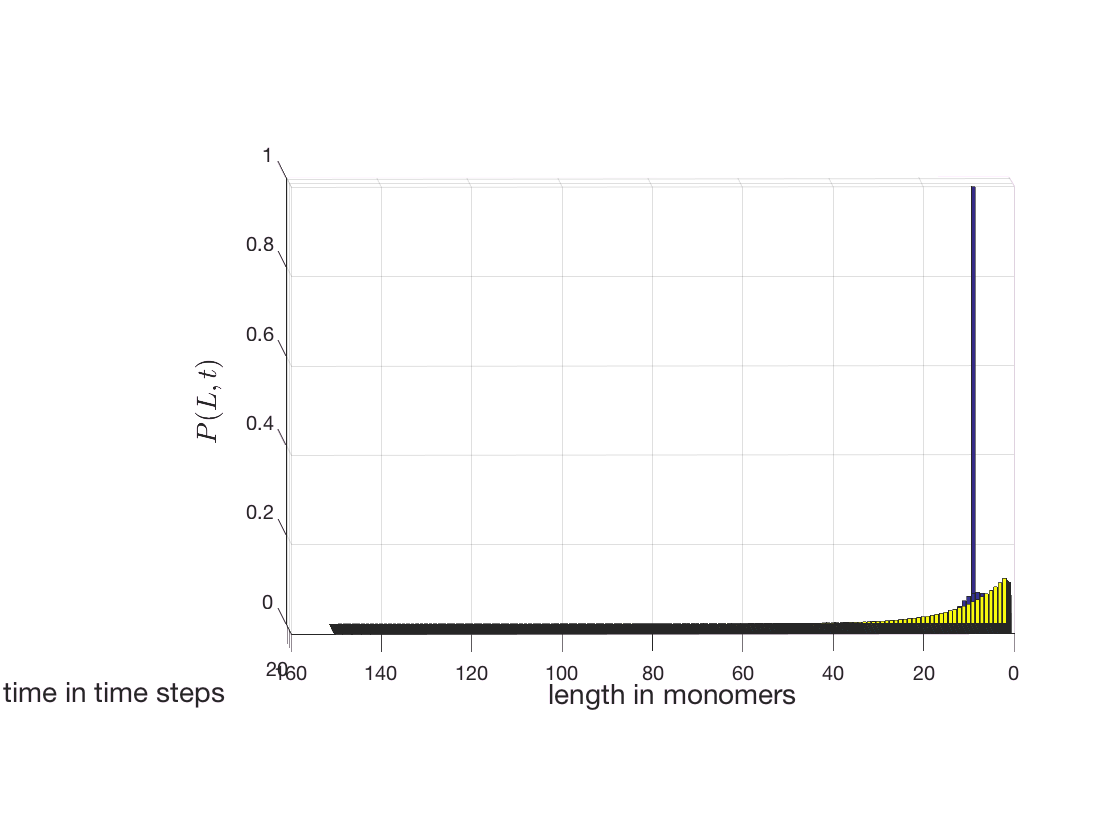

% Define the parameters. 
r = 9; % in units of inverse time
gamma = 10; % in units of inverse time
dt = 1 / 50;  % small time step!
maxLength = 150;
totalTime = 50 / dt;

% Set up the storage matrix and initial condition.
pL = zeros(maxLength, totalTime);
pL(9,1) = 1.0; % Start with no filaments

% Loop through time. 
for t=2:totalTime
    % Compute the case when L=0
    pL(1, t) = pL(1, t-1) + gamma * dt * pL(2, t-1) - r * dt * pL(1, t-1);
    
    % Loop through all of the other boxes. 
    for L=2:maxLength - 1  % so we can ignore the end case. 
        pL(L, t) = pL(L, t-1) + r * dt * pL(L-1, t-1) + ...
            gamma * dt * pL(L+1, t-1) - r * dt * pL(L, t-1) -...
            gamma * dt * pL(L, t-1);
    end
end


% Plot it. 
bar3(pL(:, 1:50:totalTime))
ylabel('length in monomers', 'FontSize', 14)
xlabel('time in time steps', 'FontSize', 14)
zlabel('$$P(L, t)$$', 'Interpreter', 'Latex', 'FontSize', 14)

Now let's plot the steady state distribution on the final time slice

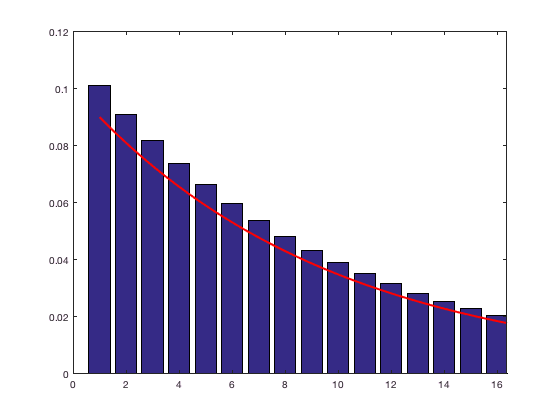

% Compute the steady-state distribution
L = linspace(1, maxLength, 1000);
dist =(1 - (r / gamma)) * (r / gamma).^L;
bins = 1:1:maxLength;

bar(bins, pL(:, totalTime))
hold on;
plot(L, dist, 'r-', 'LineWidth', 2)
hold off;

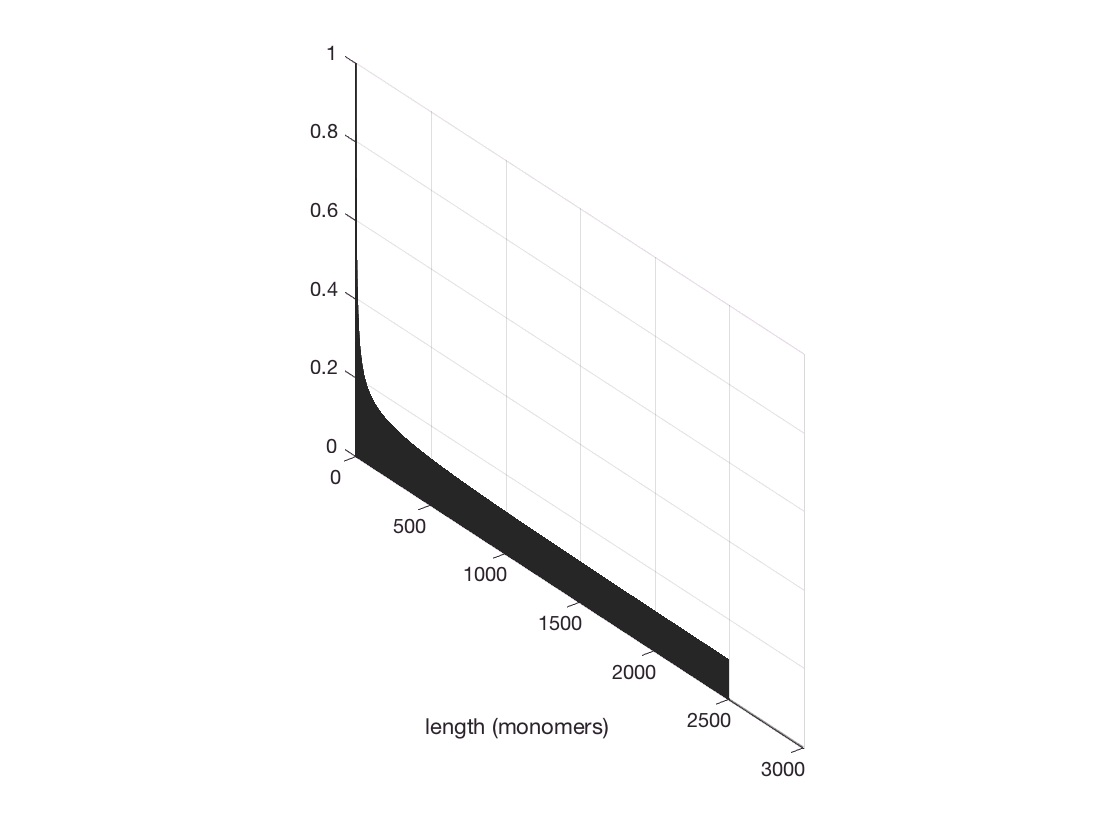

% Define the parameters.
r = 9;
gamma = 10;
dt = 1 / 50;
maxLength = 100;
totalTime = 50;
timeSteps = totalTime / dt;

% Set up the storage matrix. 
pL= zeros(timeSteps, maxLength);

% Set the initial condition. 
pL(1, 1) = 1.0;   % Start with no filaments. 

% Loop through each time step. 
for t=2:timeSteps
    % Compute the edge case. 
    pL(t, 1) =  pL(t-1,1) + gamma * dt * pL(t-1, 2) -...
        r * dt * pL(t-1, 1);

    
    % Loop through all the other lengths. 
    for b=2:maxLength - 1
        pL(t, b) = pL(t-1, b) + r * dt * pL(t-1, b-1) +...
            gamma * dt * pL(t-1,b+1) - r * dt * pL(t-1, b) -...
            gamma * dt * pL(t-1, b);
    end
end

% Plot it as a three dimensional bar plot. 
bar3(pL(:, 1:20:maxLength));
xlabel('time (steps)')
ylabel('length (monomers)')

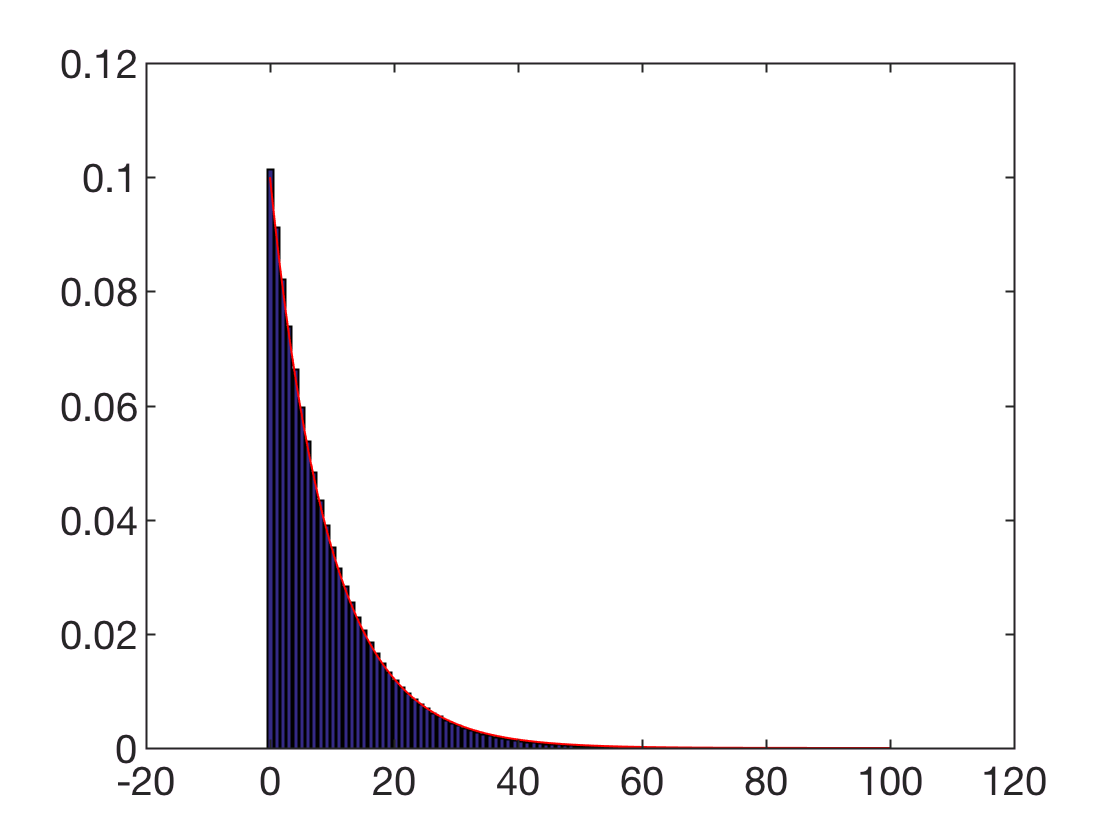



% WE can also just look at the first two time points and the last. 
bins = linspace(0, maxLength, maxLength);
bar(bins, pL(timeSteps, :));
hold on

% Plot the predicted curve
L = linspace(0, maxLength, 1000);
dist = (1 - (r / gamma)) * (r / gamma) .^ L;
plot(L, dist, 'r-')
hold off